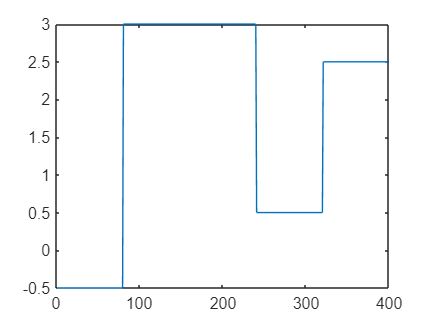

clear variables

load('uval.mat')

validation = system_simulator(1,u);

N = 300;
a = 0.5;
b = 1;

figure,
plot(u);

## Experiment for m=3

m = 3;

u_prime = zeros(1,N);

% Generate the signal using the function build below
uid1 = generator(N,m,a,b);

% Take u as the mth state of the system (line m of the signal generated)
u_original_m3 = uid1(m,1:N);

    for t = 1:N
        u_prime(t) = a+(b-a)*u_original_m3(t);
    end

% Identify an ARX model with the identification data obtained    
id_data1 = system_simulator(1, transpose(u_prime));
na = 15; 
nb = 15;
nk = 1;
model_fit_arx = arx(id_data1, [na, nb, nk]);

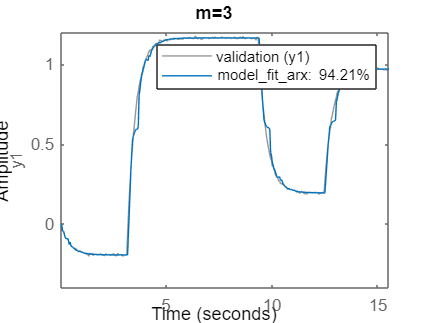


% Compare identified model output and measured output
figure,
compare(model_fit_arx,validation)
title('m=3')

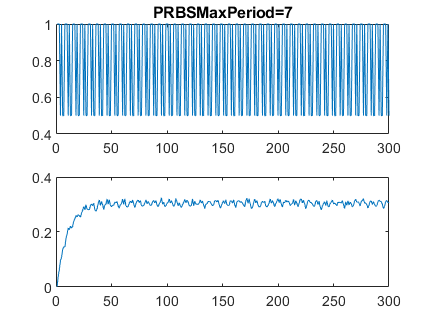


%calculate the MSE
err_squared_m3 = (validation.OutputData(1:300) - id_data1.OutputData) .^ 2;
MSE_m3 = (1/N) * sum(err_squared_m3);

PRBS_period = 2^m - 1;
figure,
subplot(211),
plot(u_prime)
title("PRBSMaxPeriod=" + PRBS_period)
subplot(212),
plot(id_data1.OutputData)

## Experiment for m=10

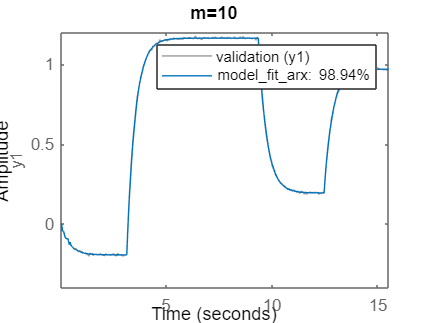

m = 10;

u_prime = zeros(1,N);

% Generate the signal using the function build below
uid2 = generator(N,m,a,b);

% Take u as the mth state of the system (line m of the signal generated)
u_original_m10 = uid2(m,1:N);

% Shift and scale the original u
    for t = 1:N
        u_prime(t) = a+(b-a)*u_original_m10(t);
    end  

% Identify an ARX model with the identification data obtained    
id_data2 = system_simulator(1, transpose(u_prime));
na = 15; 
nb = 15;
nk = 1;
model_fit_arx = arx(id_data2, [na, nb, nk]);

% Compare identified model output and measured output
figure,
compare(model_fit_arx,validation)
title('m=10')

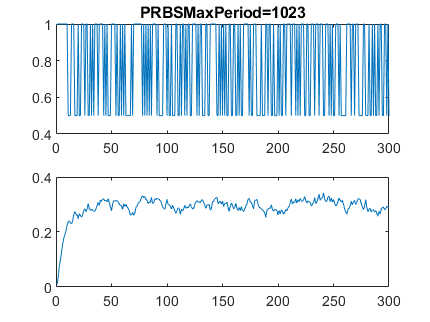


%calculate the MSE
err_squared_m10 = (validation.OutputData(1:300) - id_data2.OutputData) .^ 2;
MSE_m10 = (1/N) * sum(err_squared_m10);

PRBS_period = 2^m - 1;
figure,
subplot(211),
plot(u_prime)
title("PRBSMaxPeriod=" + PRBS_period)
subplot(212),
plot(id_data2.OutputData)

## Building the function which generates the input signal

function x = generator(N,m,a,b)

    % Building Maximum length PRBS A depending on the length m of the register (see lecture)
    if (m == 3)
        A = [1 0 1];
    elseif (m == 4)
        A = [1 0 0 1];
    elseif (m == 5)
        A = [0 1 0 0 1];
    elseif (m == 6)
        A = [1 0 0 0 0 1];
    elseif (m == 7)
        A = [1 0 0 0 0 0 1];
    elseif (m == 8)
        A = [1 1 0 0 0 0 1 1];
    elseif (m == 9)
        A = [0 0 0 1 0 0 0 0 1];
    else
        A = [0 0 1 0 0 0 0 0 0 1];
    end
    x = zeros(m,N);
    
    % Make the first column 1
    for i = 1 : 1 : m
        x(i,1) = 1; 
    end
    for k = 2 : 1 : N
        for i = 1 : 1 : m
            if(i == 1)
                sum_for_x1 = 0;
                for index = 1 : 1 : m
                    sum_for_x1 = sum_for_x1 + x(index,k-1)*A(index);
                    sum_for_x1 = mod(sum_for_x1,2);
                end
                x(i,k) = sum_for_x1;
            else
            x(i,k) = x(i-1,k-1);
            end
        end
    end
end